# Test Stable manifold

## parameters


mMoon =7.348e22;% kg
mEarth = 5.9742e24; %kg
mu = mMoon/(mMoon + mEarth)

mu =         0.0121501137626329


k = 40

k =     40



e = 0.4

e =                        0.4


Cr= 1 + e

Cr =                        1.4


Area= 110.5

Area =                      110.5


mass= 8000.0

mass =         8000



Ap = 0.001%rand(1)

Ap =                      0.001


theta = 2*pi*0.001% rand(1)

theta =        0.00628318530717959


## L2 stable


%tFinalL2 = 4.6065
%[1.2299 0 0 -0.454910328634863]
k = 100;
periodo = 3.63716374726546

periodo =           3.63716374726546


%X0 = [1.19878035065113	0	0	-0.308573433311396]
X0 = [1.198780 0 0 -0.308573];
C1 = jacobiConstant(X0(1,1:2),X0(1,3:4),mu)

C1 =           3.09461811940802


STM = reshape(eye(4),16,[])';
X = [X0 STM]';

%%% plot periodic orbit
ode__opt = odeset('RelTol',1e-14,'AbsTol',1e-22);
[t, X_periodica] = ode113(@CRTBPLyapunov, [0 periodo],X , ode__opt, mu); 

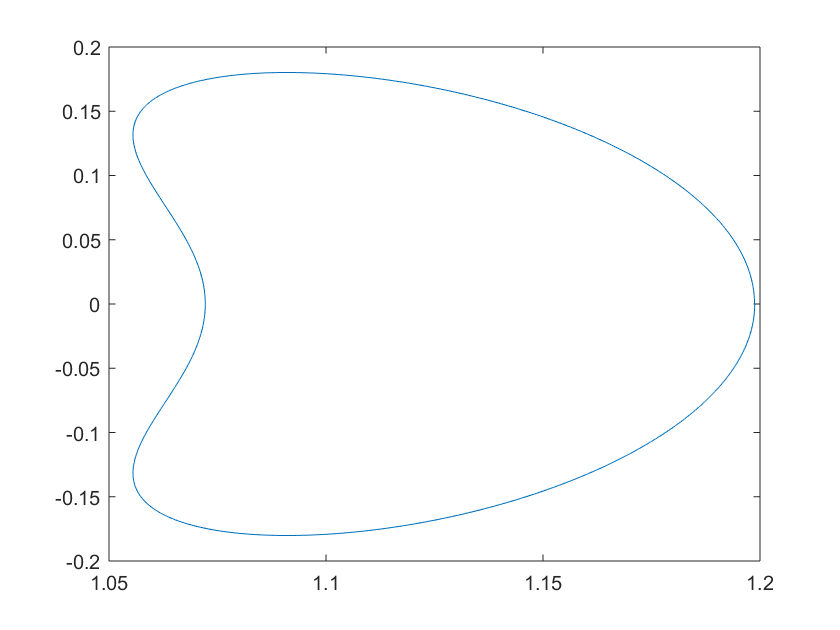

plot(X_periodica(:,1),X_periodica(:,2))

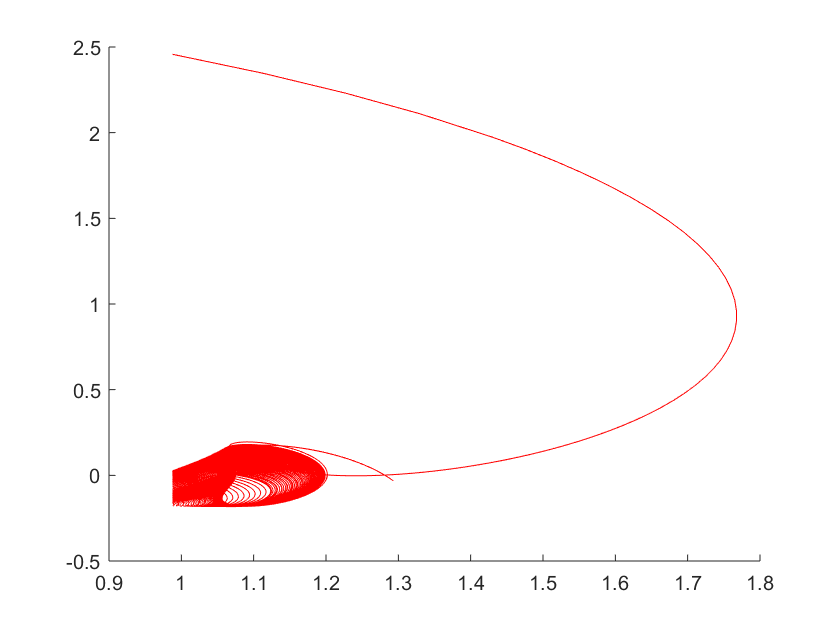

num_steps =    100


h =      1


ans =    100     4


figure

epsilon=1e-7;
%L2 stable manifold
calculateStableMainfoldPerturbation(periodo,X,mu,k,epsilon,1,true,Ap,theta,Cr,Area,mass);